绘制跟随曲线方向的箭头

此方法可以绘制一串被XY平面曲线引导方向的箭头

## 语法

## 示例

以下示例绘制子弹形曲线，然后在两翼加上沿曲线方向行进的箭头

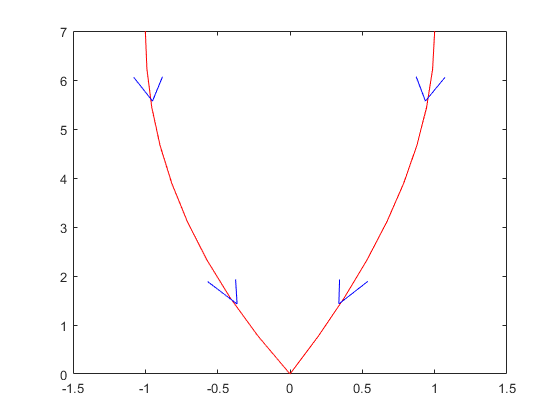

## 输入参数

XYCoordinates(1:2,:)，引导箭头方向的曲线上各点坐标。可以是第1行X，第2行Y的矩阵，也可以是实部X、虚部Y的复数行向量。

### 名称值参数

NumArrows(1,1)=width(XYCoordinates)，要绘制的箭头个数

Wingspan=1，箭头翼长，相对于坐标区

HalfRadian=pi/4，箭头展开的半弧度。此值越大，箭头越钝，大于pi/2时箭头方向反转

HalfAngle=45，箭头展开的半角度。此值越大，箭头越钝，大于90时箭头方向反转。如果指定此参数，将忽略HalfRadian

PlotArguments(1,:)cell={}，要传递给plot的其它参数。本函数使用plot绘制箭头，在这里将要使用的其它plot样式参数传递。

## 返回值

Arrows(:,1)matlab.graphics.chart.primitive.Line，代表所绘制箭头的线条对象

**See also** [plot](matlab:doc plot) [matlab.graphics.chart.primitive.Line](matlab:doc matlab.graphics.chart.primitive.Line) [pi](matlab:doc pi) [complex](matlab:doc complex)

function Arrows = LineFollowingArrow(XYCoordinates,options)
arguments
	XYCoordinates
	options.NumArrows=width(XYCoordinates)
	options.Wingspan=1
	options.HalfRadian=pi/4
	options.HalfAngle
	options.PlotArguments={}
end
if height(XYCoordinates)>1
	XYCoordinates=complex(XYCoordinates(1,:),XYCoordinates(2,:));
end
XYDiff=diff(XYCoordinates);
HasDiff=XYDiff~=0;
if isfield(options,'HalfAngle')
	HalfRadian=deg2rad(options.HalfAngle);
else
	HalfRadian=options.HalfRadian;
end
ArrowTips=imresize(XYCoordinates(HasDiff),[1,options.NumArrows]);
Directions=imresize(XYDiff(HasDiff),[1,options.NumArrows]);
WingTips=ArrowTips-Directions./abs(Directions).*[exp(HalfRadian*1i);exp(-HalfRadian*1i)]*options.Wingspan;
Arrows=[WingTips(1,:);ArrowTips;WingTips(2,:)];
Arrows=plot(real(Arrows),imag(Arrows),options.PlotArguments{:});